# Laboratorio 1 de señales

Se tomaron los respectivos datos usando una stm32 y su sensor análogo, con una función senosoidal configurada en el generador del laboratorio como se especifica en la guía.

Se tomaron muestras a una frecuencia de doscientas por segundo

Por lo que cada muestra tiene un espacio de 5ms.

Para el ejercicio propuesto se van a trabajar todos los vectores con 200 muestras (puede variar según el tiempo que se quiera graficar)

El objetivo es ver los errores de cuantificación para observar cómo afecta la resolución del sensor en la toma de muestras

archivos=["datos10hz.txt","datos20hz.txt","datos30hz.txt","datos40hz.txt",...
    "datos50hz.txt","datos60hz.txt","datos70hz.txt", ...
    "datos80hz.txt","datos90hz.txt","datos100hz.txt"];

frecuenciaMuestreo      =200;%[Hz]
frecuenciaSenal         =30;%[Hz]
tiempoGrafica           =0.5;%[s]


Seleccione el archivo de muestras a graficar:

archivoAnalizado=archivos(3);

                  

%recuperar los datos del archivo
[datosAdc,~]=importdata(archivoAnalizado);
datosAdc=datosAdc';
numeroMuestras = tiempoGrafica*frecuenciaMuestreo;

%creamos un vector de tiempo para el eje x
t=0:1/frecuenciaMuestreo:tiempoGrafica; %[s]

%recortar los datos
datosAdc=datosAdc(250:250+numeroMuestras);


%calculamos frecuencia angular
frecuenciaAngular=double(2*pi()*frecuenciaSenal);

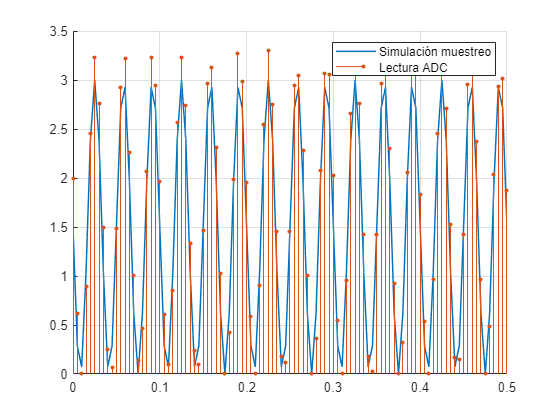

fase = 3.1416;

%se hace la simulación de muestreo
datosSim=1.5*sin(frecuenciaAngular.*t+fase)+1.5;

figure
grid on
hold on
plot(t,datosSim,LineWidth=1.1)
stem(t,datosAdc, LineWidth=0.05,MarkerSize=9,Marker=".")
legend('Simulación muestreo','Lectura ADC')


valorPsnr=psnr(datosAdc,datosSim)

valorPsnr = 11.5607

ErrorCuadraticoMedio=immse(datosAdc,datosSim)

ErrorCuadraticoMedio = 0.0698


%calcul de la media
mediaTeorica=mean(datosSim)

mediaTeorica = 1.5000

mediaExperimental=mean(datosAdc)

mediaExperimental = 1.6654

ErrorEstimacion=(abs(mediaTeorica-mediaExperimental))/mediaTeorica

ErrorEstimacion = 0.1102


%calculo de la varianza
varianzaExperimental=var(datosAdc)

varianzaExperimental = 1.3496

varianzaSimulacion=var(datosSim)

varianzaSimulacion = 1.1250

ErrorVarianzas=(abs(varianzaT-varianzaE))/varianzaT

ErrorVarianzas = 0.1996